# ***PBL Electromechanical Drives***

## Finding the points to draw the Speed/Torque profile

Lo primero que se ha realizado en este trabajo es buscar el datasheet de nuestro motor para poder obtener infotmación de cual es el perfil de Velocidad/Torque que este tiene. De esta manera podemos responder a las 3 preguntas que se nos presentan en este trabajo. 

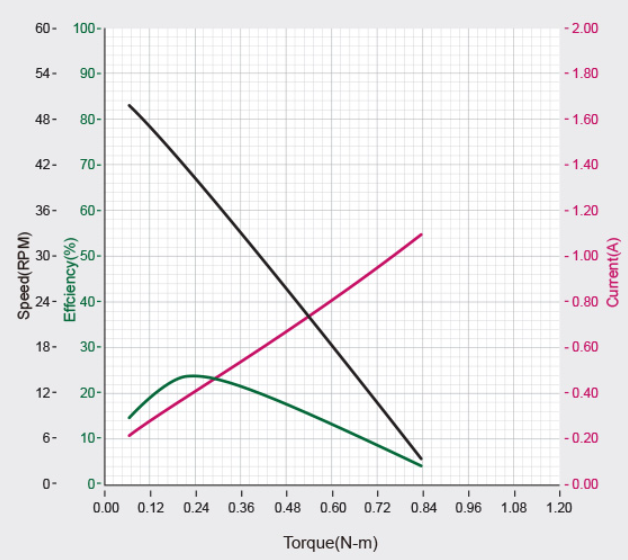

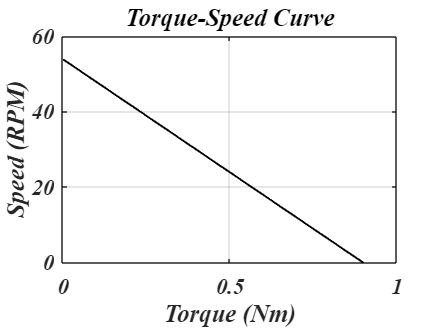

% Given data points from plot digitizer
curr_x = [0.06453483478644839, 0.4744185829884673, 0.8389535175780485];
curr_y = [0.2199710140971142, 0.6714906209856571, 1.1027496031728012];
curr_coeffs = polyfit(curr_x, curr_y, 1);

speed_x = [0.06269952967944797, 0.4685050441475022, 0.8344024106664281];
speed_y = [49.768786901476346, 26.358382535301793, 3.4732272357076224];
speed_coeffs = polyfit(speed_x, speed_y, 1);

Torque_range = 0:0.01:0.9;
% current = curr_coeffs(1) * Torque_range + curr_coeffs(2);
speed = speed_coeffs(1) * Torque_range + speed_coeffs(2);

% figure
% plot(Torque_range, current, 'r'); grid on;
% xlabel('Torque (Nm)');
% ylabel('Current (A)');
% title('Torque-Current Curve');

figure
plot(Torque_range, speed, 'k'); grid on;
xlabel('Torque (Nm)');
ylabel('Speed (RPM)');
title('Torque-Speed Curve');

## **1- Theoretical calculation of the capacity of the robot to climb a mass on a 20% slope. The maximum mass that can be carried by the robot must be calculated, depending on the target speed.**

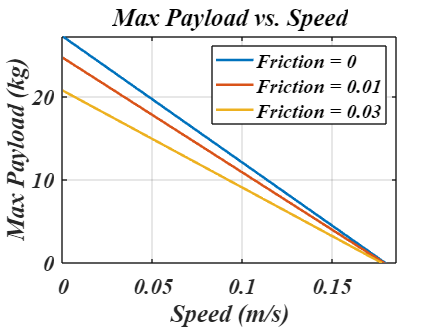

% Given data points from plot digitizer
curr_x = [0.06453483478644839, 0.4744185829884673, 0.8389535175780485];
curr_y = [0.2199710140971142, 0.6714906209856571, 1.1027496031728012];
curr_coeffs = polyfit(curr_x, curr_y, 1);

speed_x = [0.06269952967944797, 0.4685050441475022, 0.8344024106664281];
speed_y = [49.768786901476346, 26.358382535301793, 3.4732272357076224];
speed_coeffs = polyfit(speed_x, speed_y, 1);

speed_rpm = speed_coeffs(1) * Torque_range + speed_coeffs(2);

% Convert speed from RPM to m/s
RadiusOfTheWheel = 0.033; % Metres
speed = (speed_rpm * 2 * pi / 60) * RadiusOfTheWheel;


% Constants
Friction_Values = [0, 0.01, 0.03]; % Friction coefficients
g = 9.81; % Acceleration due to gravity in m/s^2
SlopeOfSystem = atand(20/100); % 20% slope (in degrees)
Turtlebot_Weight = 1; % 1 kg

% Initialize matrices for M and Max_Payload
M = zeros(length(Friction_Values), length(Torque_range));
Max_Payload = zeros(length(Friction_Values), length(Torque_range));
Force_range = 2*Torque_range/RadiusOfTheWheel; %% because we have 2 motors

% Perform calculations
for k = 1:length(Friction_Values)
    for t = 1:length(Torque_range)
        M(k, t) = (Force_range(t)/(g*(sind(SlopeOfSystem)+ 2*Friction_Values(k)*cosd(SlopeOfSystem))));    
        Max_Payload(k, t) = M(k, t) - Turtlebot_Weight; % Subtract the weight of the Turtlebot
    end
end

% Plot the results
figure;

% Plot Max_Payload vs Speed
hold on;
for k = 1:length(Friction_Values)
    plot(speed, Max_Payload(k, :), 'LineWidth', 2);
end
title('Max Payload vs. Speed');
xlabel('Speed (m/s)');
ylabel('Max Payload (kg)');
grid on;
xlim([0, max(speed)]);
ylim([0, max(Max_Payload(:))]);
legend('Friction = 0', 'Friction = 0.01', 'Friction = 0.03');


% Find and print the maximum payload for each friction value
fprintf('\nSummary of Results:\n');


Summary of Results:


fprintf('Theoretical calculation of the capacity of the robot to carry a payload on a 20%% slope was performed.\n');

Theoretical calculation of the capacity of the robot to carry a payload on a 20% slope was performed.


fprintf('The results show the maximum payload that can be carried by the robot under different conditions of friction.\n');

The results show the maximum payload that can be carried by the robot under different conditions of friction.



max_payload_for_friction = zeros(1, length(Friction_Values));

for k = 1:length(Friction_Values)
    max_payload_for_friction(k) = max(Max_Payload(k, :));
    fprintf('For friction = %.4f:\n    Max Payload = %.4f kg\n', Friction_Values(k), max_payload_for_friction(k));
end

For friction = 0.0000:
    Max Payload = 27.3515 kg
For friction = 0.0100:
    Max Payload = 24.7741 kg
For friction = 0.0300:
    Max Payload = 20.8089 kg


## **2- What must be done to increase the speed of the robot to the double of the maximum speed? Justify.**

**(We assume that we have a shunt motor)**

**        -INCREASE THE SUPPLY VOLTAGE**

The speed of a DC motor is proportional to the applied voltage. By  increasing the voltage supplied to the motor, the speed can be  increased. We can increase the input voltage from 12V to 24V to increase the speed. The reason behind this is that, in a shunt motor, the field  winding is connected in parallel with the armature winding, so the  magnetic flux ϕ remains relatively constant. Since the field current is nearly constant with varying voltage, doubling the supply voltage approximately doubles the EMF voltage, which in turn doubles the speed.Doubling the applied voltage results in a proportional increase in the speed ωω, assuming that the motor and controller can handle the increased voltage and the current remains within safe operating limits.

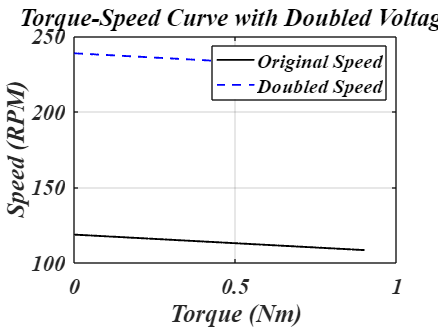

% Given data points from plot digitizer
curr_x = [0.06453483478644839, 0.4744185829884673, 0.8389535175780485];
curr_y = [0.2199710140971142, 0.6714906209856571, 1.1027496031728012];
curr_coeffs = polyfit(curr_x, curr_y, 1);

speed_x = [0.06269952967944797, 0.4685050441475022, 0.8344024106664281];
speed_y = [49.768786901476346, 26.358382535301793, 3.4732272357076224];
speed_coeffs = polyfit(speed_x, speed_y, 1);

current = curr_coeffs(1) * Torque_range + curr_coeffs(2);
speed = speed_coeffs(1) * Torque_range + speed_coeffs(2);

% Define the motor parameters
Ra = 1; % Armature resistance (Ohms), assumed value
Ke = 0.1; % Back EMF constant (V/rad/s), assumed value


% Original and doubled voltage
V_original = 12; % Original supply voltage
V_doubled = 2 * V_original; % Doubled supply voltage

% Calculate the speed for original voltage
speed_original = (V_original - current * Ra) / Ke;

% Calculate the speed for doubled voltage
speed_doubled = (V_doubled - current * Ra) / Ke;

% Plot the original and doubled speed
figure
plot(Torque_range, speed_original, 'k', 'DisplayName', 'Original Speed'); hold on;
plot(Torque_range, speed_doubled, 'b--', 'DisplayName', 'Doubled Speed'); grid on;
xlabel('Torque (Nm)');
ylabel('Speed (RPM)');
title('Torque-Speed Curve with Doubled Voltage');
legend;


fprintf('Doubling the supply voltage from %.2fV to %.2fV increases the speed.\n', V_original, V_doubled);

Doubling the supply voltage from 12.00V to 24.00V increases the speed.


**        - REDUCE THE LOAD TORQUE**

The speed of a motor decreases with increasing load torque. Reducing the load on the motor can increase its speed. Reducing the weight of the robot or the payload it carries or Improving the mechanical efficiency of the drivetrain and reducing friction losses.

We can also decrease the gear ratio by changing the number of teeth in gears so that the gear on the driven end spins faster. For example, if you change the gear ratio from 4:1 to 2:1, the output speed doubles.

**        - USE A MOTOR WITH HIGHER SPEED CONSTANT**

Using a motor with a higher speed constant (Kv) means that for the same voltage, the motor will spin faster. The Kv constant is the reciprocal  of the back EMF constant (Ke)

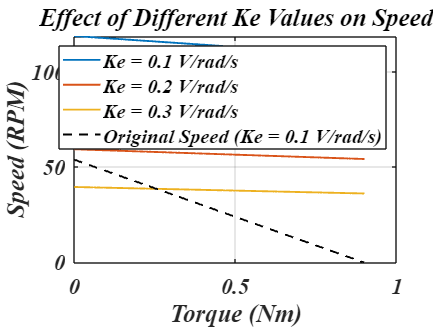

% Given data points from plot digitizer
curr_x = [0.06453483478644839, 0.4744185829884673, 0.8389535175780485];
curr_y = [0.2199710140971142, 0.6714906209856571, 1.1027496031728012];
curr_coeffs = polyfit(curr_x, curr_y, 1);

speed_x = [0.06269952967944797, 0.4685050441475022, 0.8344024106664281];
speed_y = [49.768786901476346, 26.358382535301793, 3.4732272357076224];
speed_coeffs = polyfit(speed_x, speed_y, 1);

current = curr_coeffs(1) * Torque_range + curr_coeffs(2);
speed = speed_coeffs(1) * Torque_range + speed_coeffs(2);

% Define the motor parameters
Ra = 1; % Armature resistance (Ohms), assumed value
V = 12; % Supply voltage

% Different Ke values
Ke_values = [0.1, 0.2, 0.3]; % Back EMF constants (V/rad/s)

% Initialize speed arrays
speed_values = zeros(length(Ke_values), length(Torque_range));

% Calculate speed for each Ke value
for i = 1:length(Ke_values)
    % Calculate speed using the formula: speed = (V - I * Ra) / Ke
    speed_values(i, :) = (V - current * Ra) / Ke_values(i);
end

% Plot the speed for different Ke values
figure;
hold on;
for i = 1:length(Ke_values)
    plot(Torque_range, speed_values(i, :), 'DisplayName', sprintf('Ke = %.1f V/rad/s', Ke_values(i)));
end
plot(Torque_range, speed, 'k--', 'DisplayName', 'Original Speed (Ke = 0.1 V/rad/s)'); % Original speed
grid on;
xlabel('Torque (Nm)');
ylabel('Speed (RPM)');
title('Effect of Different Ke Values on Speed');
legend;

## **3- Theoretical calculation of the capacity of a motor of the robot to lift weight vertically. The theoretical maximum mass that can be lifted at different speeds must be calculated.**

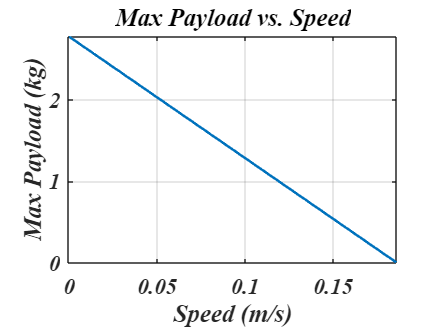

% Given data points from plot digitizer
curr_x = [0.06453483478644839, 0.4744185829884673, 0.8389535175780485];
curr_y = [0.2199710140971142, 0.6714906209856571, 1.1027496031728012];
curr_coeffs = polyfit(curr_x, curr_y, 1);

speed_x = [0.06269952967944797, 0.4685050441475022, 0.8344024106664281];
speed_y = [49.768786901476346, 26.358382535301793, 3.4732272357076224];
speed_coeffs = polyfit(speed_x, speed_y, 1);


speed_rpm = speed_coeffs(1) * Torque_range + speed_coeffs(2);

% Convert speed from RPM to m/s
RadiusOfTheWheel = 0.033; % Metres
speed = (speed_rpm * 2 * pi / 60) * RadiusOfTheWheel;

g = 9.81; % Acceleration due to gravity in m/s^2
Turtlebot_Weight = 1; % 1 kg

% Initialize matrices for M and Max_Payload
M = zeros(1, length(Torque_range));
Max_Payload = zeros(1, length(Torque_range));
Force_range = Torque_range / RadiusOfTheWheel;

% Perform calculation
for t = 1:length(Torque_range)
    M(t) = (Force_range(t) / g);
    Max_Payload(t) = M(t);
end

% Plot the results
figure;

% Plot Max_Payload vs Speed
plot(speed, Max_Payload, 'LineWidth', 2);
title('Max Payload vs. Speed');
xlabel('Speed (m/s)');
ylabel('Max Payload (kg)');
grid on;
xlim([0, max(speed)]);
ylim([0, max(Max_Payload)]);


% Find and print the maximum payload
fprintf('\nSummary of Results:\n');


Summary of Results:


fprintf('Theoretical calculation of the capacity of the robot to carry a payload vertically was performed.\n');

Theoretical calculation of the capacity of the robot to carry a payload vertically was performed.


fprintf('The results show the maximum payload that can be carried by the robot without considering friction.\n');

The results show the maximum payload that can be carried by the robot without considering friction.



max_payload = max(Max_Payload);
fprintf('Max Payload = %.4f kg\n', max_payload);

Max Payload = 2.7801 kg



fprintf('\nThe maximum payload varies depending on the applied torque and speed.\n');


The maximum payload varies depending on the applied torque and speed.



save('ideal_values.mat', 'speed', 'Max_Payload');